# Problem 3: Interplanetary flight

Student 1: Enrique Sentana Gómez

Student 2: Álvaro Reviriego Moreno

Data of the problem:

clc;
clear
close all

% Sun data
muS = 1327120e5;

% Venus low orbit data
muV = 3.24859e5;        % [km3/s2] 
aV = 10000;             % [km]
eV = 0;
OmegaV = deg2rad(30);   % [rad]
omegaV = 0;             % [rad] 
iV = deg2rad(15);       % [rad] 

% Mercury low orbit data
muM = 0.220318e5;       % [km3/s2]
aM = 5000;              % [km]
eM = 0;
OmegaM = deg2rad(50);   % [rad]
omegaM = 0;             % [rad]  
iM = deg2rad(-40);      % [rad]

## Time of flight 

This first section is devoted to develop a function which returns the time of flight between two true aniomalies following an elliptic orbit. 

First step consist on computing the eccentric anomalies $E_{1}$ and $E_{2}$ associated to each true anomaly ($\theta_{1}$ and $\theta_{2}$, respectively. In order to perform this calculation, the following two relations are used


$$sin(E) = \frac{\sqrt{1-e^2}\cdot sin(\theta)}{1+e\cdot cos(\theta)}$$
      
$$cos(E) = \frac{e + cos(\theta)}{1+e\cdot cos(\theta)}$$


Once the eccentric anomalies are calculated, it is easy to apply the following equation to compute the mean anomaly 


$$M_{e} = E - e\cdot sin(E)$$


Finally, the time of flight may be computed by applying the relation between the mean anomaly and the mean angular rate ($n_{e} = \sqrt{\frac{\mu}{a^3}}$) 


$$t_{f} = \frac{M_{e2}-M_{e1}}{n_{e}}$$


Note that, if the mean anomaly of the first position is greater than the second one, a negative time of flight will be obtained. In this case, we would add the time related to a full orbit ($t_{f}^{*} = t_{f} + \frac{2\cdot \pi}{n_{e}} $). 

The whole function is developed in [tof.m](matlab:open('./tof.m')).

## Lambert problem

Lambert's problem is one of the most popular problems in orbital mechanics. It consists on determining the COEs of an orbit given two position vectors and the time ellapsed between both. Note that this problem has two solutions, one for the long arc and the other for the short arc. Many algorithms have been developed to solve this problem. In this section, the algorithm implemented is the one in the developed in [[Avanzini, 2008](http://www.ingaero.uniroma1.it/attachments/1978_2008_JGCD_Lambert.pdf)]. 

First step on the implementation of the algorith consists on developing the function [`lambert_conic.m`](matlab:open('./Lambert_conic.m')) which computes the COEs of the orbit given the two position vectors and the transverse eccentricity. Moreover, a given vector **k **is introduced as input in order to select between the two possible solutions (long or short arc). 

In the function, first we need to compute $\Delta \theta$, defined as:


$$cos(\Delta\theta) = \frac{\vec{r_{1}} \cdot \vec{r_{2}}}{|\vec{r_{1}}||\vec{r_{2}}|}$$


Note that this relation has the two solutions already mentioned, so we will make use of the **k** vector to swtich between both. 

Once $\Delta \theta$ is computed, the following step consists on computing the chord vector **c, **defined as


$$\vec{c} = \vec{r_{2}} - \vec{r_{1}}$$


and then we may define the chord vector basis as 


$$\vec{i_{c}} = \frac{\vec{c}}{|{\vec{c}|}$$


$\vec{k_{c}} = \vec{k} $ (known as input)


$$\vec{j_{c}} = \vec{k_{c}} \times \vec{i_{c}}$$


The chord vector basis allows us to find the eccentricity component along the chord

 
$$e_{F} = -\frac{{|\vec{r_{2}}|-|\vec{r_{1}}|}}{|\vec{c}|}$$


and then define the eccentricity vector as 


$$\vec{e} = e_{F} \vec{i_{c}} + e_{T} \vec{j_{c}}$$


Then, it is easy to obtain the first COE, which is the eccentricity $e = |\vec{e}|$.

The semi-latus rectum is obtained from one of the two given position vectors, considering the following relation 


$$\vec{r} \cdot \vec{e}  = p - |\vec{r}|$$


Once the semi-latus rectum and the eccentricity are known, the semi-major axis is easily obtained 


$$a = \frac{p}{1-e^{2}}$$


It is known that the eccentricity vector always points toward the pericenter of the orbit. Hence, if the eccentricity vector is known, it can be defined the periphocal reference frame


$$\vec{i_p} = \frac{\vec{e}}{|\vec{e}|}$$
 


$$\vec{k_p} = \vec{k}$$



$$\vec{j_{p}} = \vec{k_{p}} \times \vec{i_{p}}$$


Finally, the remaining COEs ($i, \Omega, \omega$ and $\theta$) can be computed using the classical relations between the periphocal reference frame and the inertial centered one. Note that, as there are two given position vectors, there will be two true anomalies (one associated to each position).

 Once this function is implemented and the COEs are calculated, we need to integrate it in the whole algorithm which will allows us to solve the Lambert's problem. This algorith is developed in [lambert_solve.m](matlab:open('./Lambert_solve.m')), and consist on applying a bisection method looking for matching the time of flight of the of the orbit obtain with [lambert_conic.m](matlab:open('./Lambert_conic.m')) with a target time of flight introduced as input. In order to restrict the search to an ellipse, eccentricity must be between 0 and 1. 

## Hyperbola

The following function developed was [hyperbola.m](matlab:open('./hyperbola.m')). The aim of this function consist on finding the true anomaly of the parking orbit where the minimum injection impulse $\Delta v$ to go from parking orbit to hyperbolic one (or viceversa), given the COEs of the parking orbit and the velocity vector at infinity $\vec{v_{h}}$. The procedure followed by the function is the following: 

The first step is to create a linspace for the different values of $\theta$ sweeping from $0 $ to $2\pi$in 360 steps. As the COEs of the parking orbit are known, we can retrieve the position and velocity vectors at each $\theta$. Once the state vector [$\vec{r},\vec{v}$] is determined, we have to compute the normal of the orbital plane which will allow us to define the plane of the hyperbola $\vec{n} = \frac{\vec{r} \times \vec{v_{h}}}{|\vec{r} \times \vec{v_{h}|}}$. 

Once the plane is determined, the value of the impact parameter B that makes the hyperbola pass $(r,\theta)$ each can be found as it follows, where $\vec{h}=\vec{r}x\vec{v}$ , is the angular momentum of the spacecraft:


$$B = \frac{ \Vert  \vec{h}  \Vert}{ \Vert  \vec{v_{h}}  \Vert}$$


Now, the required semi-major axis and eccentricity of the hyperbola can be obtained:


$$a_{h} = -\frac{\mu}{\Vert \vec{v_{h}} \Vert ^2}$$



$$e_{h} = \sqrt{(-B/a_{h})^2 + 1}$$


Before obtaining the impulse of the maneuver, the veolicty of the hyperbola at the moment at which the change from parking orbit to hyperbola occurs needs to be computed.


$$\xi = \Vert \vec{v_{h}} \Vert^2 /2
$$



$$r_{h} = \frac{a_h(1-e_h^{2})}{1+e_{h}cos(\theta)}$$



$$v_{1h} = \sqrt{2(\xi + \mu/r_{h});$$


In addition, the velocity corresponding to the parking orbit at the same instant as the previous velocity computed, is required as well. This is done using the function [coe2stat.m](matlab:open('./coe2stat.m')) as the COE of the parking orbit are known. This function returns the position and velocity vectors, where the norm of the velocity vector corresponds to the velocity at the parking orbit $v_{p}$. Finally the impulse is computed:


$$\Delta V = \vert v_{1h}- v_{p}\vert$$


This procedure will be done for every position of $\theta$ throughout the sweep performed, the function compares the impulses at each position and returns the smallest $\Delta V$ and its corresponding $\theta$.

## Porkchop diagram

Before creating the porkchop diagram, some preparations need to be performed. First a meshgrid of departure times and travel times needs to be created, where departure times should begin in January 1, 2312, and end December 31, 2312 (note that the year 2312 is a leap-year so it has 366 days). On the other hand, travel times should range from 60 to 90 days. 

% Create departure dates, distrubute the days for 2312
% (which is a leap-year)
days = linspace(1,366,366);

% Create different travel time options
travel_times = linspace(60,90,31);

% Create meshgrid
[DAYS,TRAVEL_TIMES] = meshgrid(days, travel_times);

In addition, the COE of Venus and Mercury need to be obtained. This will be done using the ephemerides of the JPL Horizons database and selecting ephemeris type–orbital elements. These initial condtiions will be later used to compute the planet positions at each node of the time grid as needed for the porkchop diagram

% COE of Venus and Mercury from JPL Horizons database wrt ICRF in t0
% Venus
a_V = 1.082e8;              % [km]
e_V = 6.648e-3; 
i_V = deg2rad(3.392);       % [rad]
Omega_V = deg2rad(75.811);  % [rad]
omega_V = deg2rad(56);      % [rad]
theta_V = deg2rad(101.076); % [rad]
X_V(:,1) = coe2stat([a_V,e_V,i_V,Omega_V,omega_V,theta_V],muS);
E_V_init = True2Ecc(theta_V,e_V); 
Me_V_init = Ecc2Mean(E_V_init,e_V);
ne_V = sqrt(muS/(a_V^3));

% Mercury
a_M = 5.7909e7;             % [km]
e_M = 0.2056;
Omega_M = deg2rad(47.938);  % [rad]
i_M = deg2rad(6.986);       % [rad]
omega_M = deg2rad(30.015);  % [rad] 
theta_M = deg2rad(294.732); % [rad]
X_M(:,1) = coe2stat([a_M,e_M,i_M,Omega_M,omega_M,theta_M],muS);
E_M_init = True2Ecc(theta_M,e_M); 
Me_M_init = Ecc2Mean(E_M_init,e_M);
ne_M = sqrt(muS/(a_M^3));

% Propragate the orbits of Venus and Mercury
for j=2:366
    % Propagate the orbit of Venus for each day 
    Me_V_new = Me_V_init + ne_V*(days(j)-days(1))*24*3600;
    E_V_new = Mean2Ecc(Me_V_new,e_V); 
    theta_V_new = Ecc2True(E_V_new,e_V);
    X_V(:,j) = coe2stat([a_V,e_V,i_V,Omega_V,omega_V,theta_V_new],muS);
    
    % Propagate the orbit of Mercury for each day 
    Me_M_new = Me_M_init + ne_M*(days(j)-days(1))*24*3600;
    E_M_new = Mean2Ecc(Me_M_new,e_M); 
    theta_M_new = Ecc2True(E_M_new,e_M);
    X_M(:,j) = coe2stat([a_M,e_M,i_M,Omega_M,omega_M,theta_M_new],muS);
end

Now everything is prepared to start building the porkchop diagram. The procedure is to obtain the impulse required for a given combination of departure time and time travel. The total impulse is computed for long and the best solution among the two options is kept.

To obtain the impulse at each combination, first the position of Venus at departure time and the position of Mercury at the arrival time are obtained. Once these are known, the COE for the prograde transfer are obtained using [Lambert_solve.m](matlab:open('./Lambert_solve.m')). Following and required before the next step, the hyperbolic excess velocities for each departure and arrival need to be deduced:

Departure:


$$\vec{v_{h,dep}} = \vec{v_{t,dep}} - \vec{v_{0,Venus}}$$


Arrival:


$$\vec{v_{h,arr}} = \vec{v_{0,Mercury}} - \vec{v_{t,arr}} $$


Next, using [hyperbola.m](matlab:open('./hyperbola.m')), $\Delta V$ for departure and approach, and their associated $\theta$ are obtained. For the total impulse, the individual one for departure and approach are simply added. Finally this value is stored in a matrix in its corresponding position so it can be related to the associated departure time and travel time combination. Another parameter of interest is stored in the same way as for $\Delta V$, this is the characteristic energy of the hyperbolic trajectory $c_{3}$.

for jj = 1:length(days)
    % Compute the position of Venus at the departure time 
    Me_V_new = Me_V_init + ne_V*(days(jj)-days(1))*24*3600;
    E_V_new = Mean2Ecc(Me_V_new,e_V); 
    theta_V_new = Ecc2True(E_V_new,e_V);
    X_V_departure(:,jj) = coe2stat([a_V,e_V,i_V,Omega_V,omega_V,theta_V_new],muS);
        
    for kk = 1:length(travel_times)
        % Compute the position of Mercury at arrival time
        Me_M_new = Me_M_init + ne_M*(days(jj)+travel_times(kk)-days(1))*24*3600;
        E_M_new = Mean2Ecc(Me_M_new,e_M); 
        theta_M_new = Ecc2True(E_M_new,e_M);
        X_M_arrival(:,jj,kk) = coe2stat([a_M,e_M,i_M,Omega_M,omega_M,theta_M_new],muS);

        r_V = X_V_departure(1:3,jj);
        V_V = X_V_departure(4:end,jj);

        r_M = X_M_arrival(1:3,jj,kk);
        V_M = X_M_arrival(4:end,jj,kk);

        % Apply Lambert solver to determine the hyperbolic velocity at
        % departure and arrival 
        k_long = cross(r_M,r_V)/norm(cross(r_M,r_V));
        [a_t_long,e_t_long,Omega_t_long,i_t_long,omega_t_long,theta_V_t_long,theta_M_t_long] = Lambert_solve(muS,r_V,r_M,travel_times(kk),k_long);
        
        X_V_lambert_long = coe2stat([a_t_long,e_t_long,i_t_long,Omega_t_long,omega_t_long,theta_V_t_long],muS); 
        V_h_V_long = X_V_lambert_long(4:6); 
        
        [theta_hyp_V, Dv_V] = hyperbola(muV,aV,eV,OmegaV,iV,omegaV,V_h_V_long);

        X_M_lambert_long = coe2stat([a_t_long,e_t_long,i_t_long,Omega_t_long,omega_t_long,theta_M_t_long],muS);
        V_h_M_long = X_M_lambert_long(4:6);
        
        [theta_hyp_M, Dv_M] = hyperbola(muM,aM,eM,OmegaM,iM,omegaM,V_h_M_long);

        DV_long = Dv_V + Dv_M; 
        C3_long = Dv_V^2 + Dv_M^2; 

        k_short = -cross(r_M,r_V)/norm(cross(r_M,r_V));
        [a_t_short,e_t_short,Omega_t_short,i_t_short,omega_t_short,theta_V_t_short,theta_M_t_short] = Lambert_solve(muS,r_V,r_M,travel_times(kk),k_short);
        
        X_V_lambert_short = coe2stat([a_t_short,e_t_short,i_t_short,Omega_t_short,omega_t_short,theta_V_t_short],muS); 
        V_h_V_short = X_V_lambert_short(4:6); 
        
        [theta_hyp_V, Dv_V] = hyperbola(muV,aV,eV,OmegaV,iV,omegaV,V_h_V_short);

        X_M_lambert_short = coe2stat([a_t_short,e_t_short,i_t_short,Omega_t_short,omega_t_short,theta_M_t_short],muS);
        V_h_M_short = X_M_lambert_short(4:6);
        
        [theta_hyp_M, Dv_M] = hyperbola(muM,aM,eM,OmegaM,iM,omegaM,V_h_M_short);

        DV_short = Dv_V + Dv_M; 
        C3_short = Dv_V^2 + Dv_M^2;

        DV(kk,jj) = min([DV_short,DV_long]);
        C3(kk,jj) = min([C3_short,C3_long]);
    end
end

Using the function contour and using the meshgrid created initially for departure times and travel times, porkchop diagrams for $\Delta V$ and $c_{3}$ are plotted:

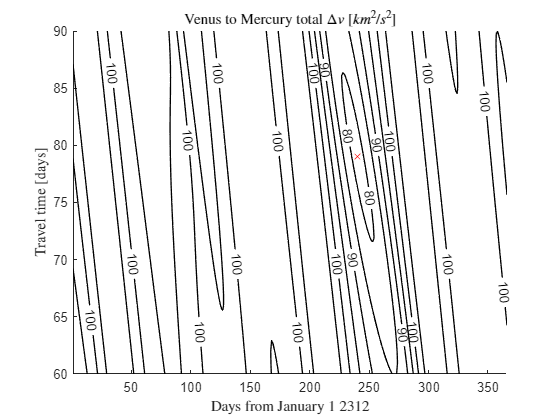

figure(1)
title('Venus to Mercury total $\Delta v$ $[km^{2}/s^{2}]$','Interpreter','latex')
xlabel('Days from January 1 2312','Interpreter','latex')
ylabel('Travel time [days]','Interpreter','latex')
hold on
[C,h]= contour(DAYS,TRAVEL_TIMES,DV,'ShowText','on','LineWidth',1,'LineColor','k');   
clabel(C,h,[80,90,100]);
[~, minIdx] = min(DV(:)); 
[row,col] = ind2sub(size(DV),minIdx); 
daysMin = DAYS(row,col); 
ttMin = TRAVEL_TIMES(row,col);
plot(daysMin, ttMin, 'rx')
hold off

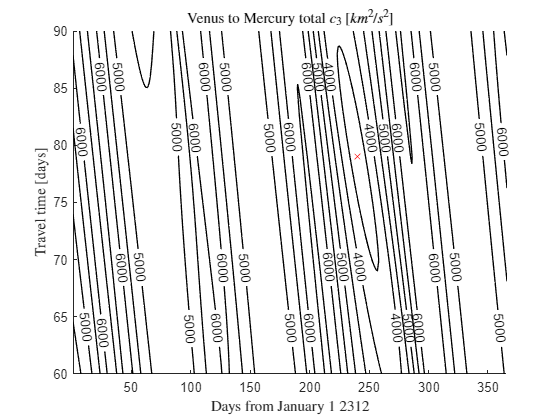

figure(2)
title('Venus to Mercury total $c_{3}$ $[km^{2}/s^{2}]$','Interpreter','latex')
xlabel('Days from January 1 2312','Interpreter','latex')
ylabel('Travel time [days]','Interpreter','latex')
hold on 
[C2,h2] = contour(DAYS,TRAVEL_TIMES,C3,'ShowText','on','LineWidth',1,'LineColor','k');
clabel(C2,h2,[4000,5000,6000]);
[~, minIdx] = min(DV(:)); 
[row,col] = ind2sub(size(C3),minIdx); 
daysMin = DAYS(row,col); 
ttMin = TRAVEL_TIMES(row,col);
plot(daysMin, ttMin, 'rx')
hold off

## Optimum travel and plots

If we analyze both porkchops, we can find that the departure day with minimum cost is 240 days after January 1 2312, i.e., on Monday September 16 2312 , and the ideal travel time is 79 days, reaching Mercury on Wednesday December 4 2312. The cost of such mission would be  $\Delta v$ = 78.7157 km/s (or $c_{3}$= 3325.1 km$^{2}$ /s$^{2}$). 

Moreover, we can plot the planetary orbits of Venus (blue) and Mercury (red) around the Sun. We must note that the final point of the animation coincides with the position of both planets at the time of optimum departure from Venus 

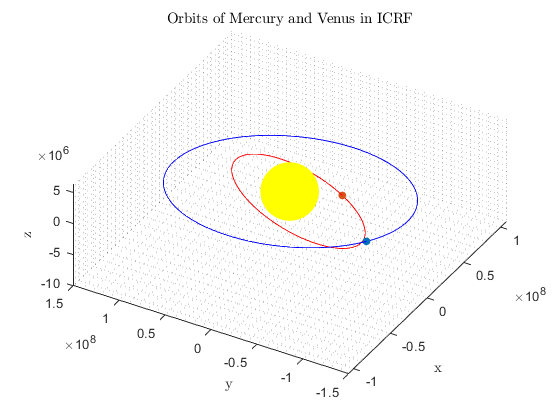

figure(3)
hold on 
xlabel('x ','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('Orbits of Mercury and Venus in ICRF','Interpreter','latex');
grid minor
view(-60,60)
plot3(0,0,0,'y.','MarkerSize',150)
plot3(X_V(1,:),X_V(2,:),X_V(3,:),'b')
plot3(X_M(1,:),X_M(2,:),X_M(3,:),'r')
for ii = 1:length(X_V)
    pointVenus = plot3(X_V(1,ii),X_V(2,ii),X_V(3,ii),'b.','MarkerSize',20);
    pointMercury = plot3(X_M(1,ii),X_M(2,ii),X_M(3,ii),'r.','MarkerSize',20);
    pause(0.05)
    delete(pointMercury)
    delete(pointVenus)
end
plot3(X_V(1,240),X_V(2,240),X_V(3,240),'.','MarkerSize',20)
plot3(X_M(1,240+79-60),X_M(2,240+79-60),X_M(3,240+79-60),'.','MarkerSize',20)

Aditionally, we can see the part of the heliocentric transfer joining both planets 

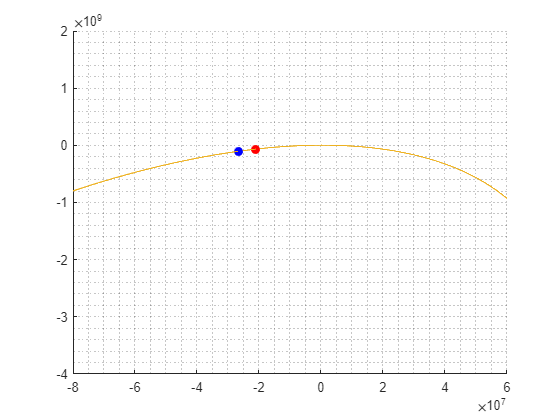

r_V = X_V_departure(1:3,240); 
r_M = X_M_arrival(1:3,240,79-60);
k_helio = cross(r_V,r_M)/norm(cross(r_V,r_M));
[a_helio,e_helio,Omega_helio,i_helio,omega_helio,thetaV_helio,thetaM_helio] = Lambert_solve(muS,r_V,r_M,79,k_helio);

theta_linspace = linspace(0,2*pi,10000);
for iii = 1:length(theta_linspace)
    X_helio(:,iii) = coe2stat([a_helio,e_helio,i_helio,Omega_helio,omega_helio,theta_linspace(iii)],muS); 
end

figure(4)
hold on 
grid minor
plot3(r_V(1),r_V(2),r_V(3),'b.','MarkerSize',20)
plot3(r_M(1),r_M(2),r_M(3),'r.','MarkerSize',20)
plot3(X_helio(1,:),X_helio(2,:),X_helio(3,:))
xlim([-8e7,6e7])
ylim([-4e9,2e9])